datastore = CLIPDatastore();
ds = shuffle(datastore)

ds =   CLIPDatastore with no properties.


[net,tokenizer] = bert();

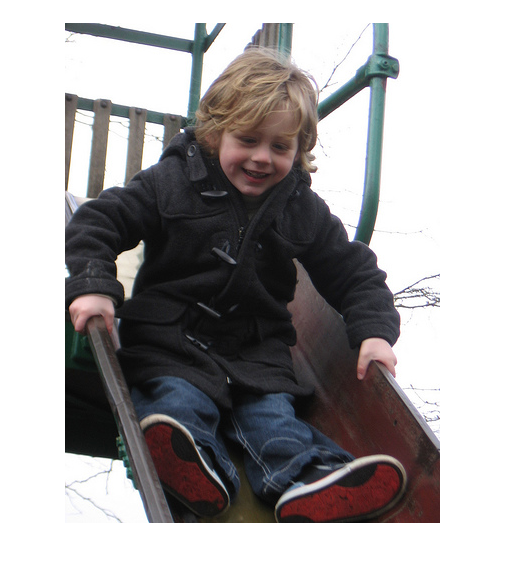

[im, tokens, caption] = read(ds);
imshow(im)

%caption = "A group of horse and their rider be race each other .";
[~, segments] = encode(tokenizer, caption);

dltoken = dlarray(tokens, 'CT');
dlsegment = dlarray(segments{1}, 'CT');
mask = dlarray(ones(1, numel(dlsegment)), 'CT');

% TODO: WHat are `mask` & `seg_ids` to the model per `net.InputNames`
pred = predict(net, dltoken, mask, dlsegment);

decode(tokenizer, tokens)

ans = "[CLS] a child be prepare to slide down a piece of playground equipment . [SEP]"

last = pred(:,end)

last =   768(C) × 1(T) single dlarray

   -1.1035
    0.0052
   -0.2304
   -0.7402
    0.0527
   -0.1226
   -0.6688
    0.1373
    0.2649
   -0.8096
    0.8361
    0.7100
    0.6602
    0.0272
    0.0831
   -0.4244
   -0.3123
    0.0168
   -0.1351
    0.1034
   -0.1283
    0.6181
    0.6648
   -0.4204
    0.6530
    0.0335
    0.0288
   -0.7982
   -0.4246
   -0.0632
    0.4782
   -0.9839
   -0.1026
   -0.0947
    0.2476
    0.4544
   -0.3329
   -0.1012
    0.9987
    0.0366
    0.0014
    0.5596
    0.7250
    0.6622
   -0.1527
   -0.6143
   -0.3199
    0.4108
   -0.7699
    0.5609
   -0.5786
    1.2148
    0.4594
    0.5372
   -0.2501
   -1.5367
    1.7043
    0.4575
   -0.4170
   -0.0767
    0.2402
   -0.7400
    0.5914
   -0.7778
    0.3170
    0.4489
   -0.3003
   -0.1175
    1.1643
    0.1469
   -0.2536
   -0.5277
   -0.3814
   -0.7095
    0.2752
   